Homework 1

% Question 2
clear all

Sigma = [1, 1, 0,
         1, 1, 0,
         0, 0, 2];
[V, D] = eig(Sigma)

V =    -0.7071    0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


D =      0     0     0
     0     2     0
     0     0     2



% A = PDPt

A = V * D * V.'

A =     1.0000    1.0000         0
    1.0000    1.0000         0
         0         0    2.0000


Question 3

% 3a)

Epsilon_Blue = [0, .5]
                0,  0]

Epsilon_Red = [0, .25,
               .25, 0]
    
Epsilon_Green = Epsilon_Red 
% Red and Green show the same deformation, but the Green one is
% translated. However, a translation is a rigid body motion and is not
% described by the elastic strain tensor

% 3b

% For a linear, isotropic, elastic medium

mu = 1 % Shear modulus

Sigma_Blue = [0, .5/2mu
              0,    0]

Sigma_Red = [0,    .25/2mu
             .25/2mu,    0]

Sigma_Green = Sigma_Red

% Epsilon(i,j)/2mu = Sigma(i,j) for components where i is not equal to j.
% For components where i=j, there is an additional term, but for all of
% these the strain is 0 in this case because they are only sheared with no
% associated volume change.

Question 4

Displacement = [0.15, 0.24,
                0.0, -0.15];
% For value in position (i, j)

% Stress(ij) = 1/2(Displacement(i,j) - Displacement(j, i)

Stress = [0.0, 0.12,
          0.12, 0];

% Rotation(ij) = 1/2(Displacement(i, j) - Displacement(j, i)
Rotation = [0.15,0.12,
            -0.12,-0.15];

Question 5

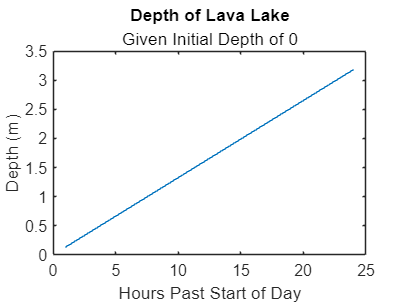

% 5a
clear all
clf

radius = 200; % Meters
fill_rate = 400000; % Cubic Meters Per Day

depth_per_day = fill_rate / (pi * radius.^2); % Meters Per Day
depth_per_hour = depth_per_day / 24; % Meters Per Hour
depth_initial = 0; % Meters

figure(1)
time = [1:1:24];
depth = (depth_per_hour * time) + depth_initial;

clf
plot(time, depth)
title('Depth of Lava Lake')
subtitle('Given Initial Depth of 0')
xlabel('Hours Past Start of Day')
ylabel('Depth (m)')

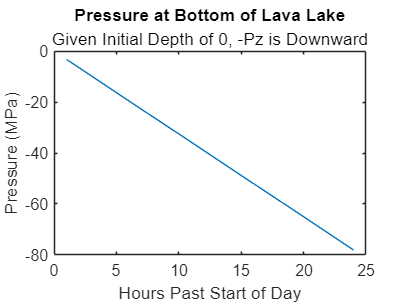


% 5b
density = 2500; % kg/m^3
gravity = 9.81; % m/s
pressure = density * gravity * depth * -1; % Pascals
pressure_mpa = pressure/1000;

figure(2)
clf
plot(time, pressure_mpa)
title('Pressure at Bottom of Lava Lake')
subtitle('Given Initial Depth of 0, -Pz is Downward')
xlabel('Hours Past Start of Day')
ylabel('Pressure (MPa)')


% 5c
v = 0.25; % Poisson's Ratio, Unitless
G = 10 * (1000^2); % Shear Modulus, Pascals (10 Gpa)
Pz = pressure(24); % Pressure after 1 day of filling
alpha_small = [0:1:radius];
alpha_large = [radius:10:(5*radius)];

% Splitting the whole model into multiple terms for readability
term_1 = ((Pz *(1-2*v)) / (4*G)); % First term
top_term_2 = 4*(1-v)*alpha_small.*(1+((alpha_small.^2) / (8.*radius^2)));
bottom_term_2 = (1-2*v) * radius;

% This approximation is only valid for alpha < r
displacement_small_alpha = term_1.*(top_term_2./bottom_term_2); % Meters

Hypergeometric function in Matlab, 2F1:

Hypergeom 2F1 takes inputs alpha, beta, gamma, x

Hypergeom(a, b, z) in Matlab can be used still if we just set a = [alpha, beta], b = gamma, and z = x

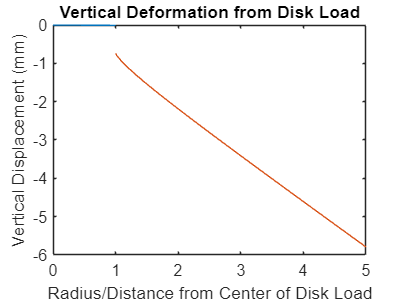

%% SECTION 2
 
term_1_large_alpha = Pz * (alpha_large.^2) * (1-2*v) * (1 / (4*G));
a = [0.5, 0.5];
b = 2;
z = (alpha_large.^2) / (radius^2);
f1_hypergeom = real(hypergeom(a, b, z)); % Real Part Only
top_term_2_large_alpha = 2 * (1-v) * f1_hypergeom;
bottom_term_2_large_alpha = (1 - 2*v) * radius;

displacement_large_alpha = term_1_large_alpha.*(top_term_2_large_alpha./bottom_term_2_large_alpha); % Meters


figure(3)
clf
ratio_small = alpha_small./radius;
ratio_large = alpha_large./radius;
plot(ratio_small,displacement_small_alpha)
hold on
plot(ratio_large,displacement_large_alpha)
title('Vertical Deformation from Disk Load')
xlabel('Radius/Distance from Center of Disk Load')
ylabel('Vertical Displacement (mm)')